# Bus Engine Replacement: From Static Logit to a Dynamic Model

**Prepared by Aaron Barkley, University of Melbourne**

This Live Script begins with a simple static random utility model and then shows what changes when choices affect future states. The dynamic example is inspired by Rust (1987), but uses simulated data and a much smaller state space. It is a teaching illustration, not a replication.

clear; clc; close all

## 1. A static random utility model

Begin with a one-time choice between replacement ($d=1$) and continuation ($d=2$). Normalize replacement utility to zero and write


$$U_1(x,\epsilon_1)=\epsilon_1,$$



$$U_2(x,\epsilon_2)=\theta_1+\theta_2x+\epsilon_2.$$


The deterministic utility difference is$\Delta u(x;\theta)=\theta_1+\theta_2x$. If the shocks are iid Type-I extreme value, the continuation probability is


$$Pr(d=2|x;\theta)=\frac{\exp[\Delta u(x;\theta)]}
 {1+\exp[\Delta u(x;\theta)]}.$$


This is an ordinary binary logit. Its structural interpretation comes from defining the logit index as the difference between the utilities of the two economic choices.

## 2. Estimating the static model

For observation$i$, the log-likelihood contribution is


$$\ell_i^{static}(\theta)=1\{d_i=2\}\Delta u(x_i;\theta)
 -\log\{1+\exp[\Delta u(x_i;\theta)]\}.$$


The code creates a teaching sample with`simulate_static_logit`.`static_logit_nll` evaluates the negative sum of the contributions above, and`fminunc` estimates the utility parameters.

Nstatic = 1000;
xStaticGrid = (0:0.9:18)';
thetaStaticTrue = [2; -0.15]; % continuation intercept and mileage coefficient
[xStatic,decisionStatic] = simulate_static_logit( ...
    Nstatic,thetaStaticTrue,xStaticGrid);

staticObjective = @(theta) static_logit_nll(theta,xStatic,decisionStatic);
staticOptions = optimoptions('fminunc','Algorithm','quasi-newton','Display','off');
[thetaStaticHat,~,exitStatic] = fminunc(staticObjective,[0; 0],staticOptions);
assert(exitStatic > 0,'Static logit did not converge')

disp(table(thetaStaticTrue,thetaStaticHat, ...
    'RowNames',{'intercept','mileage'}))

                 thetaStaticTrue    thetaStaticHat
                 _______________    ______________

    intercept             2              1.8941   
    mileage           -0.15            -0.15528   



## 3. What changes in a dynamic model?

In the static model, the index is only current utility. In a dynamic model, action$d$ changes the next-state distribution, so the relevant index is


$$\Delta v(z;\theta)=u_2(z;\theta)-u_1(z;\theta)
 +\beta\{E[V(z')|z,d=2]-E[V(z')|z,d=1]\}.$$


The likelihood retains exactly the same binary-logit form;$\Delta v$ replaces$\Delta u$. In this sense, the expected future-value difference is the only addition to the estimation formula.

Obtaining that addition is the hard part. Future values depend on later choices, which depend on the same unknown parameters and future values. Full-solution estimation resolves this fixed point at every trial value of$\theta$. CCP estimators instead use observed choice probabilities to recover information about the future-value term.

## 4. The dynamic bus replacement setting

A bus manager repeatedly chooses replacement ($d=1$) or continuation ($d=2$). The observed state is$z=(x,s)$, where mileage takes one of 21 values and$s\in\{1,2\}$ is a fixed bus type. Flow utility is


$$u_1(x,s)=0,\qquad
 u_2(x,s;\theta)=\theta_1+\theta_2x+\theta_3 1\{s=2\}.$$


The replacement normalization fixes the utility level, and the Type-I extreme-value shocks fix its scale. The discount factor is fixed at$\beta=0.9$ rather than estimated.

## 5. State transitions

Let$F_j(x'|x)$ be the mileage transition matrix under action$j$. Rows index current mileage and columns index next-period mileage. Replacement resets mileage to the first state. Under continuation, mileage can remain constant or increase, but it cannot fall. Bus type does not change, so the same mileage matrices are applied separately to each type.

## 6. Choice-specific and expected values

The choice-specific values are


$$v_1(z)=\beta\sum_{z'}F_1(z'|z)V(z'),$$



$$v_2(z;\theta)=u_2(z;\theta)
 +\beta\sum_{z'}F_2(z'|z)V(z').$$


Integrating over the Type-I extreme-value shocks gives


$$V(z)=\gamma_E+\log\{\exp[v_1(z)]+\exp[v_2(z)]\}.$$


These equations form a fixed point.`solve_model` iterates the Bellman mapping until convergence and returns$v_1$ and$v_2$ for every state.

## 7. Dynamic likelihood

Define$\Delta v(z;\theta)=v_2(z;\theta)-v_1(z;\theta)$. The dynamic choice probability and log-likelihood contribution are


$$Pr(d=2|z;\theta)=\frac{\exp[\Delta v(z;\theta)]}
 {1+\exp[\Delta v(z;\theta)]},$$



$$\ell_i^{dynamic}(\theta)=1\{d_i=2\}\Delta v(z_i;\theta)
 -\log\{1+\exp[\Delta v(z_i;\theta)]\}.$$


`fiml` implements this expression. Comparing`static_logit_nll` and`fiml` at the end makes the common logit structure visible in the code.

## 8. Data and model objects

The shared CSV contains 1,000 simulated buses observed for 15 periods. It is not the Rust (1987) data. The columns used below are`state`, the integer mileage-state index;`type`, the fixed bus type; and`decision`, coded 1 for replacement and 2 for continuation.

scriptFile = matlab.desktop.editor.getActiveFilename;
if isempty(scriptFile)
    scriptFile = mfilename('fullpath');
end
dataPath = fullfile(fileparts(scriptFile),'..','Data', ...
    'BusEngineCCP_data.csv');
data = readtable(dataPath); % simulated bus-period panel, not Rust's original data
% state: mileage-state index; type: fixed bus type; decision: 1 replace, 2 continue

x = (0:0.9:18)'; % mileage value associated with each state index
nx = length(x);
beta = 0.9; % fixed discount factor
thetaTrue = [2; -0.15; 1]; % simulation values: intercept, mileage, type 2

## 9. Mileage and replacement for one bus

The figure follows bus 1 over time. The filled markers show periods in which the manager replaces the engine; mileage resets in the following period. In this sample, replacement occurs once at mileage 5.4 and once at mileage 0.9. Higher mileage makes replacement more likely, but the Type-I extreme-value shocks make choice probabilistic rather than a fixed mileage rule. Consequently, replacement need not occur at the same mileage every time.

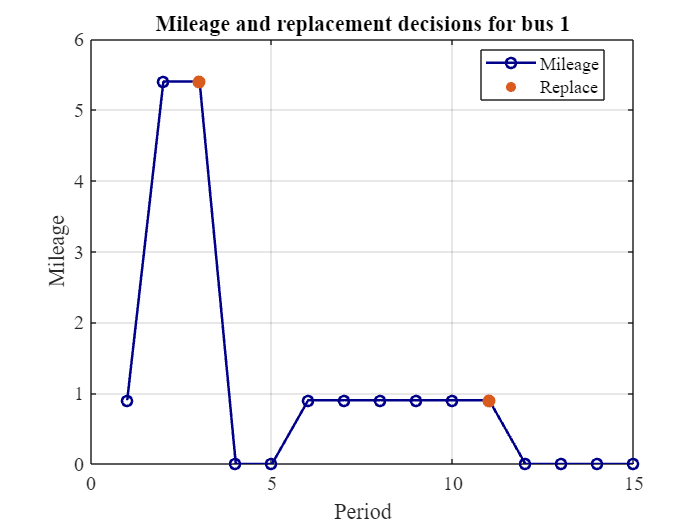

busExample = data(data.id==1,:);
replaceRows = busExample.decision==1;
figure
plot(busExample.period,busExample.mileage,'-o'); hold on
scatter(busExample.period(replaceRows),busExample.mileage(replaceRows),60,'filled')
xlabel('Period'); ylabel('Mileage')
title('Mileage and replacement decisions for bus 1')
legend('Mileage','Replace','Location','best')

## 10. Constructing and reading the transition matrices

`F1` and`F2` implement the transition distributions in the Bellman equations. The final column of`F2` collects probability beyond the finite grid. The assertions verify that every row is a probability distribution.

F1 = zeros(nx); % rows are current states; columns are next states
F1(:,1) = 1;
F2 = (x' >= x).*exp(-(x'-x))*(1-exp(-0.9)); % continue: mileage weakly rises
F2(:,end) = 1-sum(F2(:,1:end-1),2); % terminal state collects remaining mass

assert(max(abs(sum(F1,2)-1)) < 1e-12)
assert(max(abs(sum(F2,2)-1)) < 1e-12)

disp('Top-left block of replacement transition matrix F1')

Top-left block of replacement transition matrix F1


disp(F1(1:6,1:6))

     1     0     0     0     0     0
     1     0     0     0     0     0
     1     0     0     0     0     0
     1     0     0     0     0     0
     1     0     0     0     0     0
     1     0     0     0     0     0



disp('Top-left block of continuation transition matrix F2')

Top-left block of continuation transition matrix F2


disp(F2(1:6,1:6))

    0.5934    0.2413    0.0981    0.0399    0.0162    0.0066
         0    0.5934    0.2413    0.0981    0.0399    0.0162
         0         0    0.5934    0.2413    0.0981    0.0399
         0         0         0    0.5934    0.2413    0.0981
         0         0         0         0    0.5934    0.2413
         0         0         0         0         0    0.5934



Replacement is deterministic. From any current mileage state, next-period mileage is zero:


$$F_1(1{:}4,1{:}4)=
 \left[\begin{array}{c c c c}
 1&0&0&0\\1&0&0&0\\1&0&0&0\\1&0&0&0
 \end{array}\right].$$


The continuation matrix is upper triangular because mileage cannot fall:


$$F_2(1{:}4,1{:}4)\approx
 \left[\begin{array}{c c c c}
 .5934&.2413&.0981&.0399\\
 0&.5934&.2413&.0981\\
 0&0&.5934&.2413\\
 0&0&0&.5934
 \end{array} \right].$$


For example,$F_2(1,2)=0.2413$ is the probability of moving from mileage 0 to 0.9 after continuation. The entry$F_2(2,1)=0$ because mileage cannot move from 0.9 back to 0 without replacement. By contrast,$F_1(i,1)=1$ for every row$i$ because replacement resets the state deterministically.

## 11. Full-solution maximum likelihood

Each likelihood evaluation proceeds as follows.

**1. Current utility.** Given a trial$\theta$, construct


$$u_2(x,s;\theta)=\theta_1+\theta_2x+\theta_3 1\{s=2\}.$$


This is`flowContinue` inside`solve_model`; replacement flow utility is normalized to zero.

**2. Future values.** Solve the Bellman fixed point


$$V=\mathcal T_{\theta}(V),$$


using the equations for$v_1$,$v_2$, and$V$ in Section 6. This supplies the future value difference that was missing in the static logit.

**3. Choice probabilities and likelihood.** For every observation,`fiml` selects


$$\Delta v_i(\theta)=v_2(z_i;\theta)-v_1(z_i;\theta)$$


and evaluates$\ell_i^{dynamic}(\theta)$ from Section 7.

**4. Parameter update.** The estimator solves


$$\hat\theta=\arg\min_{\theta}
 \left\{-\sum_i\ell_i^{dynamic}(\theta)\right\}.$$


The optimizer proposes a new$\theta$, after which the fixed point and likelihood are recomputed. The anonymous function`objective` supplies the fixed data and model objects to`fiml`.

theta0 = [1; -0.1; 0.5];
options = optimoptions('fminunc','Algorithm','quasi-newton','Display','off');
objective = @(theta) fiml(theta,data.state,data.type,data.decision, ...
    x,F1,F2,beta);
[thetaHat,~,exitflag] = fminunc(objective,theta0,options);
assert(exitflag > 0,'FIML did not converge')

disp(table(thetaTrue,thetaHat,'RowNames',{'intercept','mileage','type 2'}))

                 thetaTrue    thetaHat
                 _________    ________

    intercept          2        2.0503
    mileage        -0.15      -0.15124
    type 2             1       0.93036



## 12. Link to the CCP exercise

Full-solution maximum likelihood repeatedly solves the dynamic program. The in-class CCP/reference-action estimator instead begins by estimating$Pr(d=1|z)$. Replacement is useful as a reference action because it resets mileage, so next-period mileage no longer depends on current mileage. This renewal structure helps recover the future-value term without resolving the Bellman equation at every trial parameter. The FIML estimates provide the benchmark for that exercise.

## Dynamic likelihood function

`fiml` implements the dynamic log likelihood. The linear index selects the correct mileage-type element from the$n_x\times2$ value arrays.

function nll = fiml(theta,state,type,decision,x,F1,F2,beta)
[v1,v2] = solve_model(theta,x,F1,F2,beta);
index = state + (type-1)*length(x); % map mileage and type to the value arrays
valueDiff = v2(index)-v1(index); % dynamic logit index: continue minus replace
softplus = max(valueDiff,0)+log1p(exp(-abs(valueDiff))); % log(1+exp(valueDiff))
nll = -sum((decision==2).*valueDiff-softplus);
end

## Bellman fixed-point solver

`V` has one row per mileage state and one column per bus type.`flowContinue` implements$u_2(x,s;\theta)$. Each iteration constructs$v_1$,$v_2$, and the integrated value from the equations above.

function [v1,v2] = solve_model(theta,x,F1,F2,beta)
gamma = 0.5772156649;
V = zeros(length(x),2);
flowContinue = [theta(1)+theta(2)*x, ... % one column for each bus type
    theta(1)+theta(2)*x+theta(3)];

for iter = 1:1000
    v1 = beta*F1*V; % replace value: zero flow utility and reset mileage
    v2 = flowContinue+beta*F2*V; % continue value: flow plus continuation value
    m = max(v1,v2);
    Vnew = m+log(exp(v1-m)+exp(v2-m))+gamma;
    if max(abs(Vnew-V),[],'all') < 1e-8
        return
    end
    V = Vnew;
end
error('Value iteration did not converge')
end

## Static data and likelihood functions

`simulate_static_logit` draws mileage and choices from the static model.`static_logit_nll` has the same likelihood form as`fiml`, but its index is only current utility; there is no continuation-value difference to solve.

function [x,decision] = simulate_static_logit(N,theta,xGrid)
rng(2026)
state = randi(length(xGrid),N,1);
x = xGrid(state); % observed mileage entering static continuation utility
index = theta(1)+theta(2)*x; % u_continue(x)-u_replace(x)
pContinue = 1./(1+exp(-index));
decision = 1+(rand(N,1)<pContinue); % 1 replace, 2 continue
end

function nll = static_logit_nll(theta,x,decision)
index = theta(1)+theta(2)*x; % no future-value term in the static model
softplus = max(index,0)+log1p(exp(-abs(index)));
nll = -sum((decision==2).*index-softplus);
end